## Question :2

 Logistic Regression. In this problem, you will learn how to implement logistic regression. You are given: i) two different training data sets: P2-data1.txt and P2-data2.txt, and ii) two different validation data sets: P2-valdata1.txt and P2-valdata2.txt. As discussed in the class, the training datasets should be used to train your selected hypothesis classes while the validation datasets should be used to select the most appropriate hypothesis class. For each data set, there are two input variables, x1 and x2, and one output variable, y. In each file, the two inputs are represented by the first two columns, and the output variable is represented by the third column. Assume that the output variable is binary, i.e., y ∈ {0, 1}. For this setup, answer the following questions. In parts (a) and (c) below, please limit your choices to the polynomial hypothesis classes of degree 6 or less. 

c) 				

clear;close all; clc;
%  Model-1 : B0 + B1X1 + B2X2 


data= load('/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Logistic regression/P2-data2.txt');
test_data = load('/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Logistic regression/P2-valdata2.txt');


% X = [data(:,1) data(:,2)  ];
% test_X = [test_data(:,1) test_data(:,2)];

% X = [data(:,1) data(:,2) data(:,1).^2 ];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 ];
% 
% X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 ];

% X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2 data(:,2).^3  ];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 test_data(:,2).^3 ];
% % 
% X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2 data(:,2).^3  data(:,1).^6 ];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 test_data(:,2).^3 test_data(:,1).^6];

% X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2 data(:,1).^3 data(:,2).^3   ];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 test_data(:,1).^2 test_data(:,2).^3 ];

% X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2 data(:,2).^3  data(:,1).^6 data(:,2).^4 data(:,2).^5];
% test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 test_data(:,2).^3 test_data(:,1).^6 test_data(:,2).^4 test_data(:,2).^5];

X = [data(:,1) data(:,2) data(:,1).^2 data(:,2).^2 data(:,2).^3  data(:,1).^6 data(:,2).^4 data(:,2).^6];
test_X = [test_data(:,1) test_data(:,2) test_data(:,1).^2 test_data(:,2).^2 test_data(:,2).^3 test_data(:,1).^6 test_data(:,2).^4 test_data(:,2).^6];
y = data(:,3);
test_y = test_data(:,3);  



for i=1:length(y)
    if y(i)== 0
        plot(data(i,1),data(i,2),'b.')
        hold on
    else 
        plot(data(i,1),data(i,2),'r+')
        hold on
    end
end
title('Dataset P2-data2.txt')
xlabel('X1')
ylabel('X2')


[m, n] = size(X);
[test_m, test_n] = size(test_X);
X = [ones(m, 1) X];
test_X = [ones(test_m, 1) test_X];
initial_Beta = zeros(n + 1, 1);
[cost, grad] = NegLogLike(initial_Beta, X, y);


fprintf('Cost for initial Parameters: %f\n', cost);

Cost for initial Parameters: 0.693147


fprintf('Gradient for Initial Parameters: \n');

Gradient for Initial Parameters: 


fprintf(' %f \n', grad);

 0.008475 
 0.018788 
 0.000078 
 0.050345 
 0.037665 
 0.023476 
 0.031031 
 0.039303 
 0.038794 



%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);
[Beta, cost] = fminunc(@(t)(NegLogLike(t, X, y)), initial_Beta, options);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


fprintf('Cost for Beta found by fminunc: %f\n', cost);

Cost for Beta found by fminunc: -1540.199973


fprintf('Beta: \n');

Beta: 


fprintf(' %f \n', Beta);

 3.072506 
 0.860272 
 2.972762 
 -6.488390 
 -2.974366 
 -1.243159 
 -4.077925 
 -3.717734 
 -3.810347 


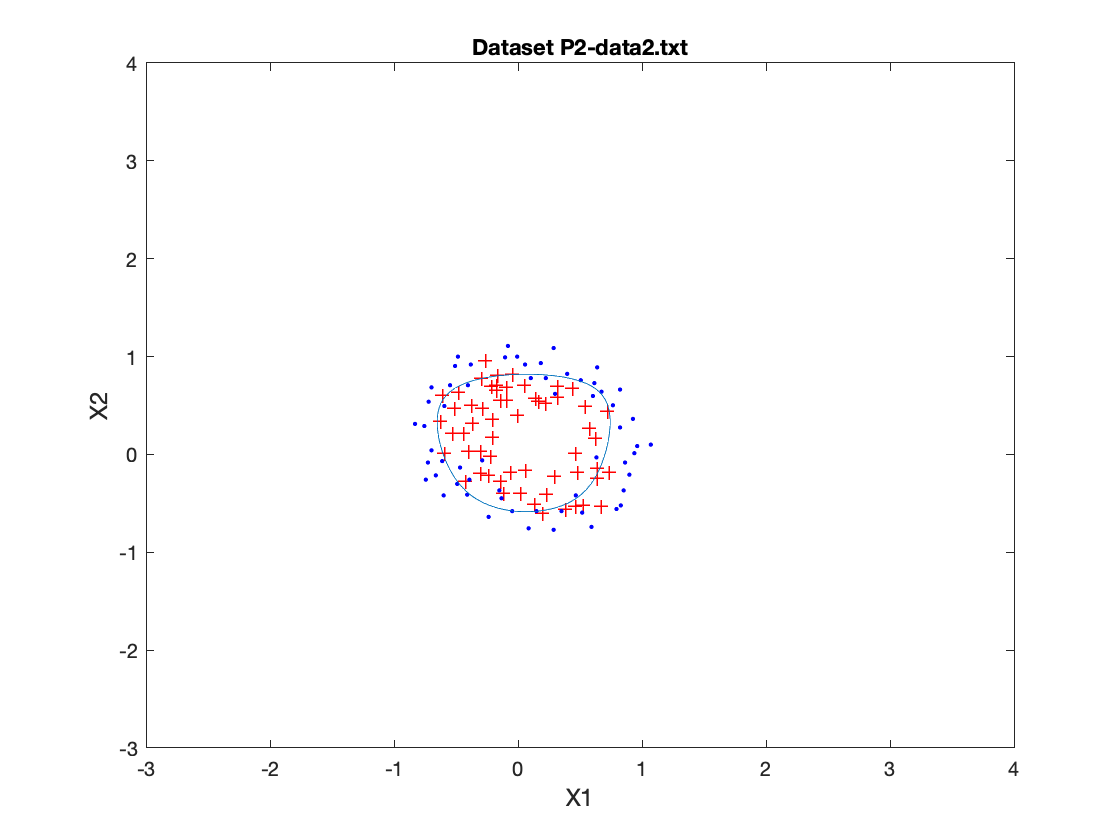


plotDecisionBoundary(data,Beta);
hold on;
xlabel('X1','FontSize',12)
ylabel('X2','FontSize',12)
p = predict(Beta, X);
test_p = predict(Beta, test_X);
hold off



for i=1:length(test_y)
    if test_y(i)== 0
        plot(test_data(i,1),test_data(i,2),'b.')
        hold on
    else 
        plot(test_data(i,1),test_data(i,2),'r+')
        hold on
    end
end
title('Dataset P2-valdata2.txt')
xlabel('X1')
ylabel('X2')



fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 79.661017


Model_error = 100 - (mean(double(p == y)) * 100);
fprintf('Training Error : %f Percent\n',Model_error);

Training Error : 20.338983 Percent



fprintf('Test Accuracy: %f\n', mean(double(test_p == test_y)) * 100);

Test Accuracy: 85.000000


test_Model_error = 100 - (mean(double(test_p == test_y)) * 100);
fprintf('Test Error : %f Percent\n',test_Model_error);

Test Error : 15.000000 Percent


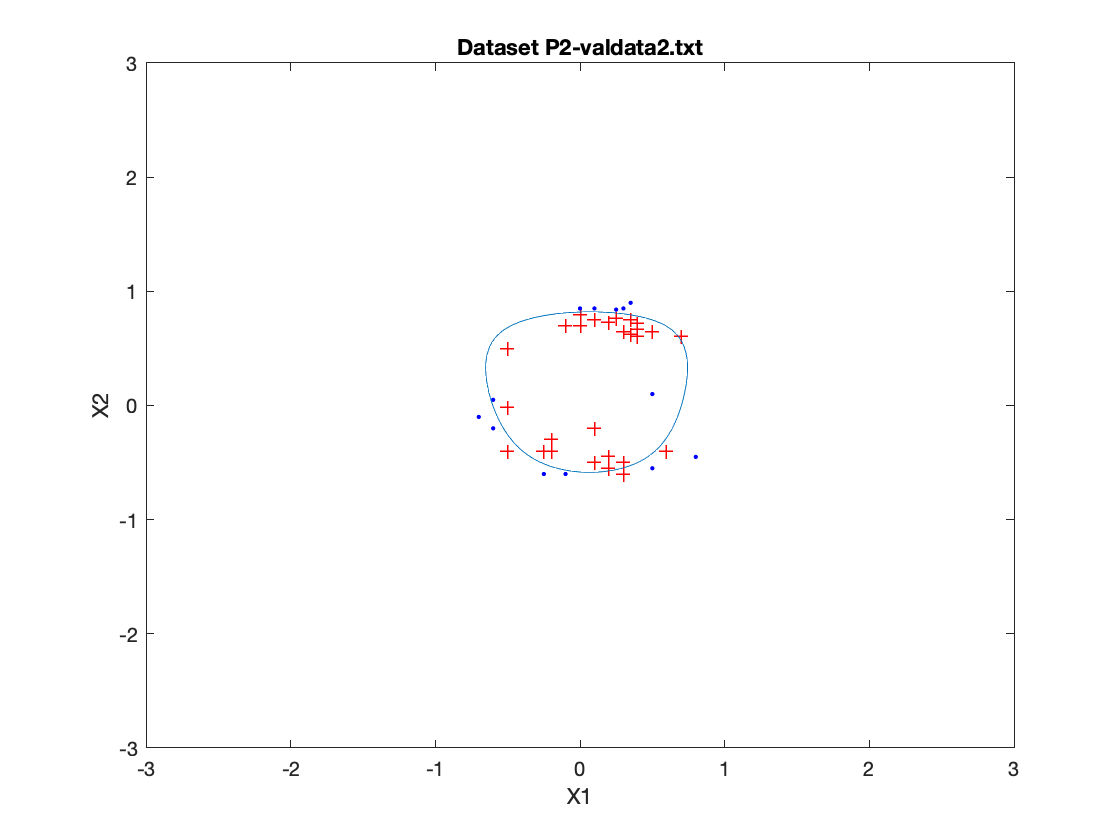


plotDecisionBoundary(test_data,Beta);
hold off

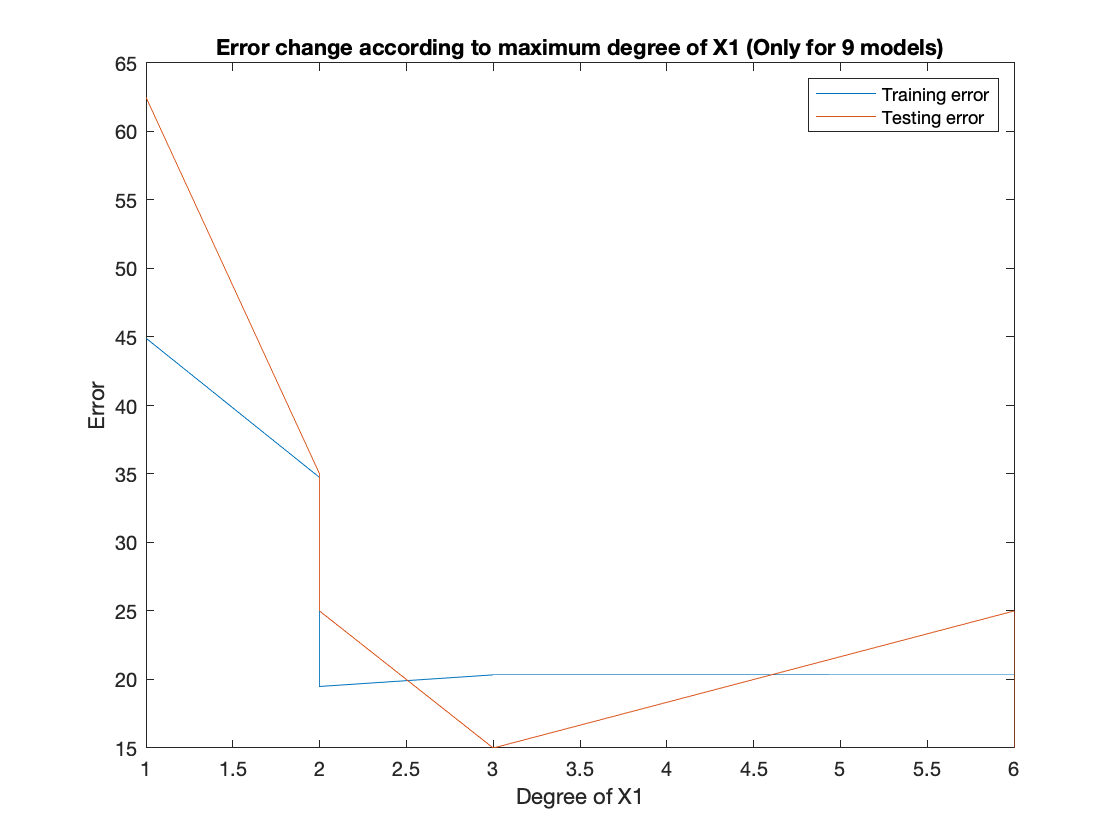


%The following matrix was made with trying different models and listing down the
%training and testing errors.
%For the errors with respect to different degrees.
%error_degree_mat = [max degree of X1 , max degree of X2, Training error, Test error] 


error_degree_mat = [1 1 44.915 62.5;2 1 34.745 35; 2 2 21.18644 25;2 3 19.4915 25;3 3 20.3389 15;6 3 20.33 25;6 4 21.1864 15;6 5 21.18644 15;6 6 20.3389 15 ] ;
plot(error_degree_mat(:,1),error_degree_mat(:,3),error_degree_mat(:,1),error_degree_mat(:,4))
title('Error change according to maximum degree of X1 (Only for 9 models)')
xlabel('Degree of X1')
ylabel('Error')
legend({'Training error','Testing error'})

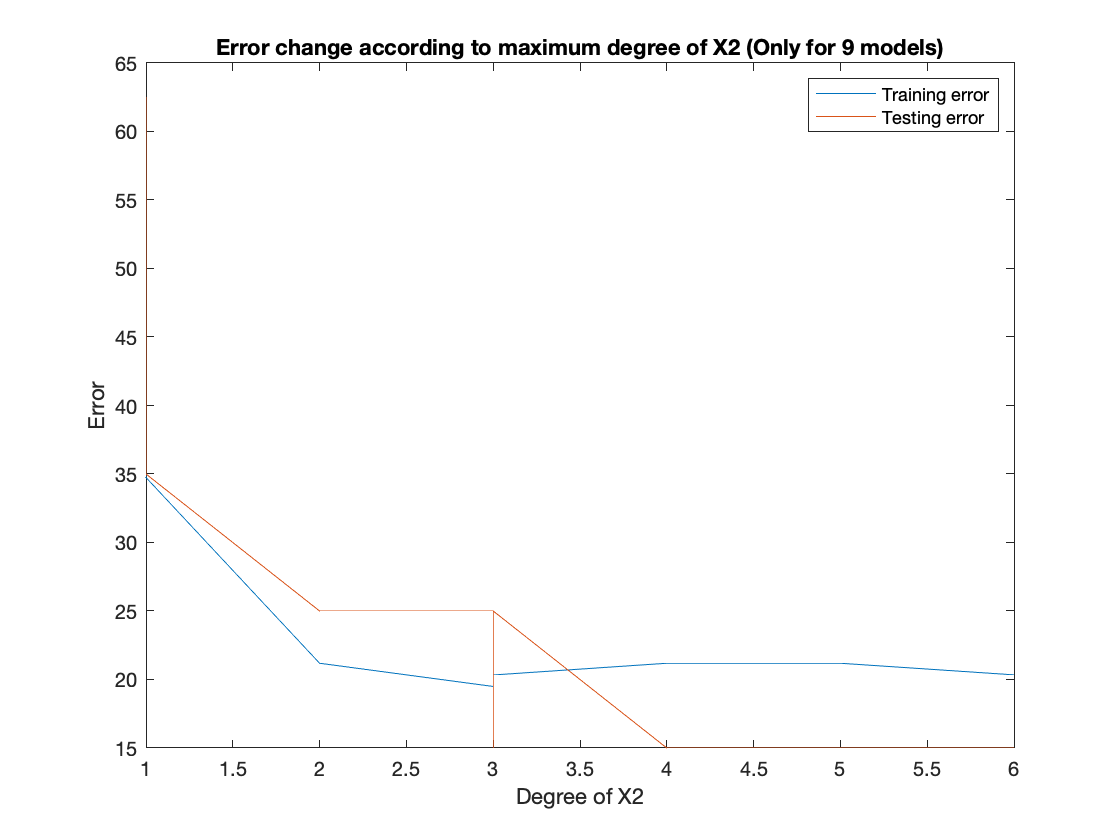

plot(error_degree_mat(:,2),error_degree_mat(:,3),error_degree_mat(:,2),error_degree_mat(:,4))
title('Error change according to maximum degree of X2 (Only for 9 models)')
xlabel('Degree of X2')
ylabel('Error')
legend({'Training error','Testing error'})

function [J, grad] = NegLogLike(Beta, X, y)

m = length(y); 
lemda = 100;

J=1./(m)*(sum(((-y'.*log(1./(1+exp(-Beta'*X'))))-((1-y)'.*log(1-1./(1+exp(-Beta'*X')))))+ lemda *sum(Beta)));
grad=1./m*(1./(1+exp(-Beta'*X')) -y')*X;


end

function plotDecisionBoundary(data,Beta)
%plot(data(:,1:2), y);
hold on
% y_1 = @(x,y) Beta(1)+Beta(2).*x+Beta(3).*y+Beta(4).*x.^2+Beta(5).*y.^2+Beta(6).*x.^3+Beta(7).*y.^3; 
% fimplicit(y_1,[min(data(:,1))-2 max(data(:,1))+2 min(data(:,2))-2 max(data(:,2))+2]);

y_1 = @(x,y) Beta(1)+Beta(2).*x+Beta(3).*y+Beta(4).*x.^2+Beta(5).*y.^2+Beta(6).*y.^3+Beta(7).*x.^6+Beta(8).*y.^4 +Beta(9).*y.^6; 
fimplicit(y_1,[min(data(:,1))-2 max(data(:,1))+2 min(data(:,2))-2 max(data(:,2))+2]);
hold off
end

function p = predict(Beta, X)
m = size(X, 1); 
p = zeros(m, 1);
for i=1:m  
    c = -Beta'*X(i,:)';
    p(i) = 1./(1.+exp(c));
    if p(i)>= 0.5
        p(i)=1; 
    else 
        p(i)=0 ;
    end
end
end

